# Exercise 1: Antenna Array Analysis with Custom Radiation Pattern

Number of steps: 4 

Expected completion time: 15 minutes

In this section, an antenna array with cosine and custom antenna radiation pattern is created and the array's response pattern is analyzed. Custom element pattern can be obtained either from measurements or from simulations. 

clear
close all

## Create Cosine Antenna Element 

The initial step in simulating an antenna array's performance is to define its fundamental building block: the single antenna element. The Phased Array System Toolbox offers a library of predefined antenna elements (e.g., `phased.IsotropicAntennaElement`, `phased.GaussianAntennaElement`). You can find a complete list of antenna element objects and functions in the [Phased Array System Toolbox documentation](https://www.mathworks.com/help/phased/referencelist.html).

In this step we will instantiate a `phased.CosineAntennaElement` object. This element should be configured to operate over a frequency range from 1 GHz to 1.25 GHz. Set the specific operating frequency to 1.25 GHz for plotting purposes. Plot the 3D radiation pattern of this single cosine antenna element to visualize its spatial response.

freqVector  = [1 1.25].*1e9;        % Frequency range for element pattern 
antenna1 = phased.CosineAntennaElement( ...
    'FrequencyRange',freqVector, 'CosinePower',1.5);
fmax = freqVector(end);  % display Radiation pattern at f=fmax 
pattern(antenna1,fmax,'Type','powerdb')

## Create a Custom Antenna Element (***phased.CustomAntennaElement)***

This exercise shows you how to define an antenna element using a custom spatial response pattern rather than a predefined one. The `phased.CustomAntennaElement` System object allows you to model antennas with either polarized or non-polarized fields.

### Import Your Custom Radiation Pattern

You can import a custom radiation pattern obtained from measurements or simulations (e.g., HFSS). Your simulated radiation pattern should be an **M-by-3 matrix** where:

- The **first column** represents the **azimuth angle (****ϕ****)**.

- The **second column** represents the **elevation angle (****θ****)**.

- The **third column** represents the **radiation pattern in dB**.

**Important:** The azimuth angle (ϕ) should be between −180∘ and 180∘, and the elevation angle (θ) should be between −90∘ and 90∘.

For this exercise, we'll use the provided helper function, `helperPatternImport.m`, to read a CSV file containing a custom antenna pattern. This cardioid-shaped pattern was simulated using the ϕ−θ convention and saved as a CSV file. The `helperPatternImport` function will read this file and reformat its contents into a two-dimensional matrix suitable for use with `phased.CustomAntennaElement`.

% use helper function (helperPatternImport.m) to read .csv file and reformat into 2-D Matrix.
filename='custompattern.csv';
[pattern_phitheta,phi,theta] = helperPatternImport(filename);

Verify MATLAB workspace variables: phi, theta and pattern_phitheta.

### Create Custom Antenna Element using imported radiation pattern

Now, we will use the imported ϕ-θ radiation pattern to define a custom antenna element. Assume this antenna operates over a frequency range of 1 GHz to 1.25 GHz.

%------------------------------
% ADD CODE HERE
% Hint: use phased.CustomAntennaElement function to create antenna element using imported
% data. Type 'doc phased.CustomAntennaElement' into the command line interface 
% for more information. 
% Supply the FrequencyVector (freqVector), PatternCoordinateSystem ('phi-theta'), PhiAngles (phi), ThetaAngles
% (theta), MagnitudePattern (pattern_phitheta)).
% Name the output object 'antenna2'.  
% ------------------------------
antenna2     = phased.CustomAntennaElement('FrequencyVector',freqVector, ...
                              'PatternCoordinateSystem','phi-theta',...
                              'PhiAngles',phi,...
                              'ThetaAngles',theta,...
                              'MagnitudePattern',pattern_phitheta);

### Plot Imported Antenna Element Radiation pattern

To verify that the pattern has been correctly imported, plot the response of the custom antenna element at selected frequency value. 

fmax = freqVector(end);  % display Radiation pattern at f=fmax 
%-----------------------------------
% ADD CODE HERE
% Hint: use 'pattern' function to plot radiation pattern for 'antenna2'element.
% Type 'doc phased.URA/pattern' into the command line interface for more information.  
% Supply fmax as frequency for plot, for 'Type' parameter specify 'powerdb'

%--------------------------------
pattern(antenna2,fmax,'Type','powerdb')

Notice that the main beam points to $0^\circ$ azimuth and $90^\circ$ elevation. The custom pattern with main beam along z-axis is imported without any rotation.

## Construct Antenna Array: Uniform Rectangular Array 

In this step, you will construct two 64-element Uniform Rectangular Arrays (URAs). Each URA will have its elements arranged on an 8-by-8 rectangular grid.

**Objective:**

- Create the **first URA** using the `phased.CosineAntennaElement` as its individual antenna element.

- Create the **second URA** using the `phased.CustomAntennaElement` that you defined in the previous step (based on the imported radiation pattern).

**Important Note on Element Spacing:** To prevent the appearance of grating lobes, ensure that the elements in both URAs are spaced at **one-half wavelength (****λ****/2****)** corresponding to the **highest operating frequency** of your antenna.

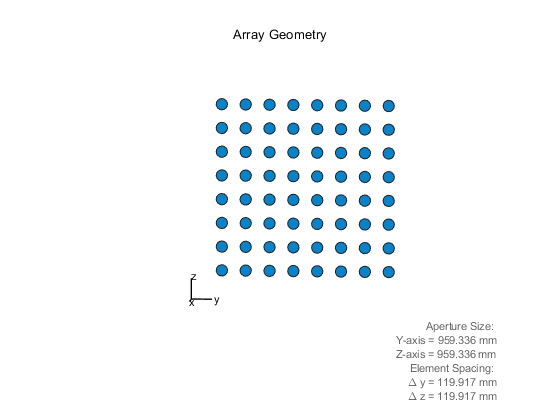

c = physconst('LightSpeed');
lambda = c/fmax;
% create an URA using cosine element antenna1
array1 = phased.URA('Element',antenna1,'Size',8,'ElementSpacing',lambda/2);
%--------------------------
% ADD CODE HERE
% Hint: use phased.URA function to create an array using a custom antenna element
% created in a previous step. Type 'doc phased.URA' into the command line interface 
% for more information. 
% Supply the Element (antenna2), Size (8), ElementSpacing (lambda/2).
% Name the output object 'array2'.  
% Verify 'array2' object in your workspace
% ------------------------------
array2 = phased.URA('Element',antenna2,'Size',8,'ElementSpacing',lambda/2);

## Plot Array Radiation Pattern in 3D

Visualize the 3D radiation patterns for both `array1` (the URA with cosine elements) and `array2` (the URA with custom elements) using the `pattern` function from the Phased Array System Toolbox. 

%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use 'pattern' function to plot array radiation pattern for both array1 and array2.
% Type 'doc phased.URA/pattern'into the command line interface for more information.  
% Supply fmax as frequency for a plot, 'PropagationSpeed' (c) and for 'Type' ('powerdb')

%--------------------------------
pattern(array1,fmax,'PropagationSpeed',c,'Type','powerdb')
pattern(array2,fmax,'PropagationSpeed',c,'Type','powerdb')

### Plot Array Radiation Pattern versus Azimuth

In this step, you will visualize the **total radiation pattern** of your antenna arrays as a function of azimuth angle. Remember that the total array pattern is a multiplication of the individual element pattern and the array factor.

figure;
patternAzimuth(array1,fmax,0,'PropagationSpeed',c,'Type','powerdb'); % array1 2D pattern for theta=0
hold on
patternAzimuth(array2,fmax,0,'PropagationSpeed',c,'Type','powerdb'); % array2 2D pattern for theta=0
hold off;
allLineHandles = findall(gca, 'Type', 'line');
legend(allLineHandles, {'URA with Cosine Element', 'URA with Custom Element'})

## Exercise Question 

- **Why and when would it be beneficial to use a "Custom Radiation Pattern"** (e.g., from measurements or simulations) to define an antenna element in a phased array system, as opposed to using a predefined element model like `phased.CosineAntennaElement`? Discuss the advantages and potential scenarios where this approach is crucial.

- **Array Design Choices:** What are the primary advantages and disadvantages of using a URA geometry for an antenna array?Beyond the URA, what **other array geometries** exist (e.g., Uniform Linear Array (ULA), Uniform Circular Array (UCA), conformal arrays)? Briefly describe a scenario where one of these alternative geometries might be preferred over a URA, and explain why.

## Summary

This exercise demonstrated how to construct and analyze antenna arrays using **both a predefined cosine antenna element and a custom antenna pattern**. Key takeaways include:

- **Defining Custom Elements:** We explored how a custom radiation pattern, often generated from full-wave modeling simulation software following the ϕ-θ convention, can be used to form a `phased.CustomAntennaElement`.

- **Array Construction:** The exercise showed how to integrate both standard (cosine) and custom antenna elements into a Uniform Rectangular Array (URA).

- **Pattern Analysis:** We visualized and compared the 3D and 2D radiation patterns of arrays built with these different element types, highlighting the significant influence of the individual element's response on the overall array performance.